Load data

dataInputraw = load("pricevolumedata.mat") ;

dataInput = dataCleaningFcn_v2(dataInputraw)

dataInput = struct with fields:
    closepriceTT: [2930×665 timetable]
     highpriceTT: [2930×665 timetable]
      indexclean: [2930×6 timetable]
      lowpriceTT: [2930×665 timetable]
     openpriceTT: [2930×665 timetable]
        volumeTT: [2930×665 timetable]



openpriceTT     = dataInput.openpriceTT ;
highpriceTT     = dataInput.highpriceTT ;
lowpriceTT      = dataInput.lowpriceTT ;
closepriceTT    = dataInput.closepriceTT ;
volumeTT        = dataInput.volumeTT ;

clear dataInputraw

Define walk window dataset

% lookback upper bound
lookbackUB = 250;

% Number of step for training datastasket
nstepTrain = 500;

% Number of step for testing dataset
nstepTest = 20;
% Number of step per walk dataset
nstepIST = lookbackUB + nstepTrain;
nstepOST = nstepTest;

% Number of walk for the whole walk forwad
nWalk = 36 ;
nstepWalk = nWalk*nstepOST + nstepIST;

% Number of rows in raw data
rowsData = size (closepriceTT,1) ;
% dataSet.openpriceTT = openpriceTT ;
% dataSet.highpriceTT = highpriceTT ;
% dataSet.lowpriceTT = lowpriceTT ;
% dataSet.closepriceTT = closepriceTT ;
% dataSet.volumeTT = volumeTT ;

Walk forward 

startTimer = tic ; 

nvars = 11 ; % number variables in optimParams to be optimizeds

% Preallocate
T = repmat (table(zeros(nWalk,1)),1,2+nvars)  ;
tableHeader = {'iteration', 'optimEndDate', 'volumeMAtreshold',...
               'volumeMAlookback', 'valueThreshold', 'valueLookback',...
               'volumeValueBufferDays', 'priceRetLowCloseThresh', 'priceMAThreshold',...
               'priceMAlookback', 'priceVolumeValueBufferDays',...
               'cutlossLookback', 'cutlosspct'} ;
T.Properties.VariableNames = tableHeader ;

timCOlumn = table(transpose ((datetime(2017,11,1:nWalk)))) ;
timCOlumn.Properties.VariableNames = {'optimEndDate'};

optimParamsTable = [T(:,1) timCOlumn(:,1) T(:,3:13) ];


i = 1

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 2 3 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 6).
Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     76    50     5     8    10    12   121    23     5     5     8


fval = -5.7923

exitflag = 0

outpt = struct with fields:
        elapsedtime: 396.6565
          funccount: 300
    constrviolation: 0
               ineq: [-0.0494 -2.8228 0 -0.2674 -0.2105]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 401.5158

optimParams_i =     76    50     5     8    10    12   121    23     5     5     8


i = 2

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    241   191    24     5     3     7   119    30     5     4     8


fval = -1.8221

exitflag = 0

outpt = struct with fields:
        elapsedtime: 310.2982
          funccount: 300
    constrviolation: 0
               ineq: [-0.0028 -0.9988 0 -0.2371 -0.1942]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 310.9438

optimParams_i =    241   191    24     5     3     7   119    30     5     4     8


i = 3

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     98   190     5     3     8    13    86    23     3     2     6


fval = -3.6308

exitflag = 0

outpt = struct with fields:
        elapsedtime: 309.5938
          funccount: 300
    constrviolation: 0
               ineq: [-0.0292 -2.0069 0 -0.2487 -0.1941]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 309.9038

optimParams_i =     98   190     5     3     8    13    86    23     3     2     6


i = 4

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    199   159     8    10     9     5   171    11     4     4     2


fval = -1.3307

exitflag = 0

outpt = struct with fields:
        elapsedtime: 293.3500
          funccount: 300
    constrviolation: 0
               ineq: [-0.1392 -0.5087 0 -0.2995 -0.2892]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 293.5659

optimParams_i =    199   159     8    10     9     5   171    11     4     4     2


i = 5

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    242   193    26     4     2     2   115    30     4     3     8


fval = -2.1688

exitflag = 0

outpt = struct with fields:
        elapsedtime: 290.0939
          funccount: 300
    constrviolation: 0
               ineq: [-0.0052 -1.0900 0 -0.1814 -0.1614]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 290.2321

optimParams_i =    242   193    26     4     2     2   115    30     4     3     8


i = 6

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    250   196    26     3     2     2   115    30     4     3     8


fval = -2.1777

exitflag = 0

outpt = struct with fields:
        elapsedtime: 273.0185
          funccount: 300
    constrviolation: 0
               ineq: [-0.0092 -0.8969 0 -0.1937 -0.1654]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 273.0763

optimParams_i =    250   196    26     3     2     2   115    30     4     3     8


i = 7

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    250   189    23     4     3     2   123    26     4     3     8


fval = -1.5966

exitflag = 0

outpt = struct with fields:
        elapsedtime: 287.9342
          funccount: 300
    constrviolation: 0
               ineq: [-0.0325 -0.5852 0 -0.1933 -0.1971]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 288.0158

optimParams_i =    250   189    23     4     3     2   123    26     4     3     8


i = 8

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    142   181     5     9     5     6   168    14     4     1     2


fval = -1.6812

exitflag = 0

outpt = struct with fields:
        elapsedtime: 331.3123
          funccount: 300
    constrviolation: 0
               ineq: [-0.0901 -0.9796 0 -0.2724 -0.2474]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 331.3514

optimParams_i =    142   181     5     9     5     6   168    14     4     1     2


i = 9

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     61   120     5     4    10    12   136    21     4     1     5


fval = -2.1093

exitflag = 0

outpt = struct with fields:
        elapsedtime: 287.6115
          funccount: 300
    constrviolation: 0
               ineq: [-0.0110 -1.6899 0 -0.1642 -0.2174]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 287.6423

optimParams_i =     61   120     5     4    10    12   136    21     4     1     5


i = 10

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    250   196    24     5     2     3   126    28     3     3     6


fval = -1.6223

exitflag = 0

outpt = struct with fields:
        elapsedtime: 249.8839
          funccount: 300
    constrviolation: 0
               ineq: [-0.0965 -1.2375 0 -0.2551 -0.2498]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 249.9270

optimParams_i =    250   196    24     5     2     3   126    28     3     3     6


i = 11

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    244   194    26     3     2     4   126    28     3     1     5


fval = -1.8770

exitflag = 0

outpt = struct with fields:
        elapsedtime: 243.8534
          funccount: 300
    constrviolation: 0
               ineq: [-0.0917 -1.6302 0 -0.2681 -0.2521]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 243.9469

optimParams_i =    244   194    26     3     2     4   126    28     3     1     5


i = 12

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    236   191    24     5     2     6   123    30     3     5     8


fval = -1.4879

exitflag = 0

outpt = struct with fields:
        elapsedtime: 268.3639
          funccount: 300
    constrviolation: 0
               ineq: [-0.0848 -1.1595 0 -0.2348 -0.2598]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 268.4202

optimParams_i =    236   191    24     5     2     6   123    30     3     5     8


i = 13

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    212    89     5    10     9     5   119    26     5     5     4


fval = -2.4299

exitflag = 0

outpt = struct with fields:
        elapsedtime: 266.0138
          funccount: 300
    constrviolation: 0
               ineq: [-0.0025 -1.7747 0 -0.2198 -0.1965]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 266.0364

optimParams_i =    212    89     5    10     9     5   119    26     5     5     4


i = 14

Objective or constraint function returned NaN.
No solution found that satisfies the nonlinear constraints.


sol =    177   189    21     9     7     5   193    16     4     1     2


fval = -1.0179

exitflag = -2

outpt = struct with fields:
        elapsedtime: 277.0803
          funccount: 300
    constrviolation: 5.0000e-04
               ineq: [-0.1487 -0.4255 5.0000e-04 -0.2995 -0.2987]
           rngstate: [1×1 struct]
            message: 'No solution found that satisfies the nonlinear constraints.'


endTime = 277.2181

optimParams_i =    177   189    21     9     7     5   193    16     4     1     2


i = 15

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    208   199     5    10     9     6   122    15     3     2     5


fval = -2.5111

exitflag = 0

outpt = struct with fields:
        elapsedtime: 252.8681
          funccount: 300
    constrviolation: 0
               ineq: [-0.0051 -1.4020 0 -0.1616 -0.1851]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 252.9349

optimParams_i =    208   199     5    10     9     6   122    15     3     2     5


i = 16

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    124   137     5     3    10    14   117    30     5     3     5


fval = -2.3938

exitflag = 0

outpt = struct with fields:
        elapsedtime: 235.3920
          funccount: 300
    constrviolation: 0
               ineq: [-0.0199 -2.0085 0 -0.2621 -0.1732]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 235.4369

optimParams_i =    124   137     5     3    10    14   117    30     5     3     5


i = 17

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    250   163     5    10     5     1   123    12     3     1     3


fval = -1.6585

exitflag = 0

outpt = struct with fields:
        elapsedtime: 202.3704
          funccount: 300
    constrviolation: 0
               ineq: [-0.0152 -1.1210 0 -0.1652 -0.1837]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 202.4464

optimParams_i =    250   163     5    10     5     1   123    12     3     1     3


i = 18

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    225   192     5     9     5     4   179    12     4     2     4


fval = -1.0580

exitflag = 0

outpt = struct with fields:
        elapsedtime: 271.5379
          funccount: 300
    constrviolation: 0
               ineq: [-0.1373 -0.6653 0 -0.2873 -0.2873]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 271.6079

optimParams_i =    225   192     5     9     5     4   179    12     4     2     4


i = 19

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     60   117    41     9     2    12    65    27     4     3     7


fval = -1.5428

exitflag = 0

outpt = struct with fields:
        elapsedtime: 289.3449
          funccount: 300
    constrviolation: 0
               ineq: [-0.0700 -0.6524 0 -0.2359 -0.2393]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 289.3950

optimParams_i =     60   117    41     9     2    12    65    27     4     3     7


i = 20

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     67   122    41     9     3    13    63    25     5     5     8


fval = -1.6355

exitflag = 0

outpt = struct with fields:
        elapsedtime: 269.1738
          funccount: 300
    constrviolation: 0
               ineq: [-0.0331 -0.7730 0 -0.2402 -0.2372]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 269.2289

optimParams_i =     67   122    41     9     3    13    63    25     5     5     8


i = 21

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     73   134     5     7     9    13    67    23     4     5     4


fval = -3.6920

exitflag = 0

outpt = struct with fields:
        elapsedtime: 277.9154
          funccount: 300
    constrviolation: 0
               ineq: [-0.0108 -1.4423 0 -0.1943 -0.2057]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 278.1375

optimParams_i =     73   134     5     7     9    13    67    23     4     5     4


i = 22

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    172   144    14     9     6    13    99    16     3     5     4


fval = -2.6736

exitflag = 0

outpt = struct with fields:
        elapsedtime: 264.8967
          funccount: 300
    constrviolation: 0
               ineq: [-0.0521 -1.3047 0 -0.2136 -0.2343]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 265.1500

optimParams_i =    172   144    14     9     6    13    99    16     3     5     4


i = 23

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     61    85    41     5     2    12    72    16     5     5     8


fval = -2.4458

exitflag = 0

outpt = struct with fields:
        elapsedtime: 303.2564
          funccount: 300
    constrviolation: 0
               ineq: [-0.0183 -1.1522 0 -0.2122 -0.2095]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 303.3211

optimParams_i =     61    85    41     5     2    12    72    16     5     5     8


i = 24

Objective or constraint function returned NaN.


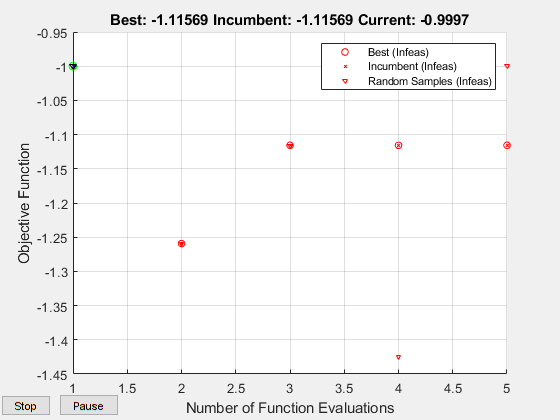

Error using parallel.ProcessPool/parfeval (line 56)
Out of Memory during serialization

Error in globaloptim.bmo.ModelManager/evaluateRemote (line 322)
                self.pendingTrials(end).task = parfeval(self.pool, ... 

Error in 

for i = 24:nWalk
    i
    % steps per walk
    OSTend_i = rowsData - nstepOST*(nWalk-i) ;
    OSTstart_i = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    % Define data set per walk
    % ISTdataSet
    ISTdataSet_i.openpriceTT    = openpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.highpriceTT    = highpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.lowpriceTT     = lowpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.closepriceTT   = closepriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.volumeTT       = volumeTT(ISTstart_i:ISTend_i,:) ;
    
    % Optimize optimParams per walk
    startOptimPoint = size(ISTdataSet_i.openpriceTT,1) - nstepTrain;
    
    optimParams_i = optimParamsFcn_v5 (ISTdataSet_i, startOptimPoint) 

    % Save optimparams per walk
    timeColumn = ISTdataSet_i.openpriceTT.Time ;
    timeISTend_i = datetime(timeColumn(end,:),'InputFormat','yyyy-MM-dd') ;
    
    optimParamsTable(i,1).Variables = i ;
    optimParamsTable(i,2).Variables = timeISTend_i ;
    optimParamsTable(i,3:13).Variables = optimParams_i ;

end


EndTimer = toc(startTimer)  
timehours = EndTimer/(60*60)

Walk forward on optimizaed parameters in each walk

% Preallocate OSTportDailyRetTT 
% OSTportDailyRetTT = repmat(openpriceTT (1,1),nWalk*nstepOST,1) ;
OSTportDailyRetTT = openpriceTT (1,1) ;
OSTportDailyRetTT.Properties.VariableNames = "OSTportDailyRet" ;

% Preallocate netDailyRetperSymTT
% OSTnetDailyRetperSymTT = repmat(closepriceTT (1,:), nWalk*nstepOST,1) ;
OSTnetDailyRetperSymTT = closepriceTT (1,:);
sym = OSTnetDailyRetperSymTT.Properties.VariableNames ;
sym = eraseBetween (sym, 5,10) ;
OSTnetDailyRetperSymTT.Properties.VariableNames  = sym ;

% Preallocate tradingSignalTT 
OSTtradingSignalTT = OSTnetDailyRetperSymTT ;

for i = 1:nWalk
    
    % steps per walk
    OSTend_i    = rowsData - nstepOST*(nWalk-i) ;
    OSTstart_i  = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    % Params i
    paramsInput_i   = optimParamsTable(i,3:13).Variables;
    maxlookback     = max (paramsInput_i) ;
    
    % Define dataset
    % OSTdataSet
    OSTdataSet_i.openpriceTT    = openpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.highpriceTT    = highpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.lowpriceTT     = lowpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.closepriceTT   = closepriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.volumeTT       = volumeTT(OSTstart_i-maxlookback:OSTend_i,:) ;

    % Calculate portCumRet in OST
    tradingSignalTT_i = tradingSignalFcnVectorized_v1 (paramsInput_i, OSTdataSet_i) ;
    [portDailyRetTT_i, netDailyRetperSymTT_i] = tradingBacktestFcn_v2 (tradingSignalTT_i, OSTdataSet_i);
        
    % Concatenate OSTportDailyRetTT
    OSTnetDailyRetperSymTT_i = netDailyRetperSymTT_i(end-nstepOST+1:end,:) ;
    OSTnetDailyRetperSymTT = [OSTnetDailyRetperSymTT; OSTnetDailyRetperSymTT_i ] ;
    
    % Concatenate OSTportDailyRetTT
    portDailyRetTT_i.Properties.VariableNames = OSTportDailyRetTT.Properties.VariableNames  ;
    OSTportDailyRetTT_i = portDailyRetTT_i(end-nstepOST+1:end,:) ;
    OSTportDailyRetTT = [OSTportDailyRetTT; OSTportDailyRetTT_i]  ;

    % Concatenate tradingSignalTT
    OSTtradingSignalTT_i = tradingSignalTT_i(end-nstepOST+1:end,:) ;
    OSTtradingSignalTT = [OSTtradingSignalTT; OSTtradingSignalTT_i] ;

end

OSTtradingSignalTT (1,:)       = []
OSTnetDailyRetperSymTT (1,:)   = []
OSTportDailyRetTT (1,:)        = []


Analyze the results

plot chart animation

% Plot animated chart with pause or drawnow function
% Plot portCumRetTT    
% Plot animated chart with pause or drawnow function
for i = 1:nWalk
%     i = 2
    walk_i = i 

    walkStart_i = 1+ nstepOST*(i-1)
    walkEnd_i = walkStart_i + nstepOST-1
    OSTportDailyRetTT_i = OSTportDailyRetTT(1:walkEnd_i, :);
    
    OSTportCumRetTT = ret2tick (OSTportDailyRetTT_i) ;

    semilogy(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)
%     plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)
    drawnow 
    pause(2);

end
    


Statistics

% OSTportCumRetTT = ret2tick (OSTportDailyRetTT) ;
% 
% plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)

% CAGR
timeVar = OSTportCumRetTT.Time ;
OSTportCumRet = OSTportCumRetTT.Variables ;
OSTportCumRetEnd = OSTportCumRet(end,:)
nYear = yearfrac (timeVar(1,:), timeVar(end,:))
CAGR = ((OSTportCumRet (end,:) / OSTportCumRet (1,:))^(1/nYear))-1

% Drawdown
[MDD,MaxDDIndex] = maxdrawdown(OSTportCumRetTT.Variables) ;
MaxDD = MDD 
drawDownTime = timeVar(MaxDDIndex)


Number signal daily

nDailySignal = sum (OSTtradingSignalTT.Variables,2)
nDailySignalTT = OSTportCumRetTT
nDailySignalTT.Variables = nDailySignal

% plot daily signal
plot(nDailySignalTT.Time , nDailySignalTT.Variables )


Rank symbol based on cumulative return

symRank = rankSymbolsFcn (OSTnetDailyRetperSymTT)


Discretionary

OSTCumRetperSymTT = ret2tick(OSTnetDailyRetperSymTT) ;

plot(OSTCumRetperSymTT.Time, OSTCumRetperSymTT.JSKY)

Save optimParams to matfile

% Save optimParams to matfile
optimParams_filename = "optimParams.mat";
save (optimParams_filename , "optimParamsTable") 
